warning on backtrace

### 1. Read the video file and define its size and frames

videosquence = 'foreman_cif-1.yuv';     % original yuv file
width = 352;                            % original yuv width
height = 288;                           % original yuv height
nframes = 10;                           % number of yuv frames
blocked_frame_cell_array = cell(1,300); % Storage for blocked frame, no meaningful use in algo., good visualizer

% extract Y, padding and blocking
A1_Q3_extract_YOnly(videosquence, height, width, nframes);

Y-only files Y!


### 2. Exercise1-a. ﻿For every specific target set of configs...

% I_periods = [1, 4, 10];
% searchRanges = [1, 4, 8];
% ns = [1, 2, 3];
% nRefFrames = [1, 2, 3, 4];
% VBSEnables = [false, true];
% FMEEnables = [false, true];
% FastMEs = [false, true];

I_periods = [4, 10];
searchRanges = [16];
ns = [1];
nRefFrames = [1];
VBSEnables = [false];
MRFoverlays = [0];
FMEEnables = [false];
FastMEs = [false]; 

combinations = A3_combineConfigs(I_periods, searchRanges, ns, ...
    nRefFrames, VBSEnables, MRFoverlays, FMEEnables, FastMEs);

combinations(:, 5) = logical(combinations(:, 5));
combinations(:, 7) = logical(combinations(:, 7));
combinations(:, 8) = logical(combinations(:, 8));

filename_prefix = "A3_Q1_a_";

QPs = 0:9;
blockSizes = [4, 8, 16, 32, 64];
% RCflag = false;
% targetBR = inf;
% 
% IAverageBitCounts = zeros(length(blockSizes), length(QPs));
% PAverageBitCounts = zeros(length(blockSizes), length(QPs));
% 
% for blockSize_idx = 1:length(blockSizes)
%     blockSize = blockSizes(blockSize_idx);
% 
%     for QP_idx = 1:length(QPs)
% 
%         QP_value = QPs(QP_idx);
%         iTotalBitCounts = 0;
%         iTotalRowCounts = 0;
%         pTotalBitCounts = 0;
%         pTotalRowCounts = 0;
% 
%         fprintf('Processing QPs: %d with block size: %d.\n', QP_value, blockSize);
%         for comb_idx = 1:size(combinations, 1)
%             [paddedWidth, paddedHeight] = A1_Q3_paddingAndBlocking(width, height, blockSize, ...
%                 blocked_frame_cell_array, nframes);
%             I_period = combinations(comb_idx, 1);
%             searchRange = combinations(comb_idx, 2);
%             n = combinations(comb_idx, 3);
% 
%             nRefFrame = combinations(comb_idx, 4);
%             VBSEnable = combinations(comb_idx, 5);
%             MRFoverlay = combinations(comb_idx, 6);
%             FMEEnable = combinations(comb_idx, 7);
%             FastME = combinations(comb_idx, 8);
% 
%             isIFrame = @(x) mod(x-1, I_period) == 0;
%             iFrameIdx = arrayfun(isIFrame, 1:nframes);
%             pFrameIdx = arrayfun(@(x) ~isIFrame(x), 1:nframes);
% 
%             [~, bitConsumptionPerFrame, rowBlockCountPerFrame] = A3_Encoding( ...
%                 filename_prefix, nframes, paddedWidth, paddedHeight, ...
%                 blockSize, height, width, searchRange, n, I_period, QP_value, ...
%                 nRefFrame, VBSEnable, MRFoverlay, FMEEnable, FastME, ...
%                 RCflag, targetBR, [], [], [], []);
% 
%             bitConsumptionsInIFrame = bitConsumptionPerFrame(iFrameIdx);
%             rowBlockCountInIFrame = rowBlockCountPerFrame(iFrameIdx);
%             iTotalBitCounts = iTotalBitCounts + sum(bitConsumptionsInIFrame);
%             iTotalRowCounts = iTotalRowCounts + sum(rowBlockCountInIFrame);
% 
%             bitConsumptionsInPFrame = bitConsumptionPerFrame(pFrameIdx);
%             rowBlockCountInPFrame = rowBlockCountPerFrame(pFrameIdx);
%             pTotalBitCounts = pTotalBitCounts + sum(bitConsumptionsInPFrame);
%             pTotalRowCounts = pTotalRowCounts + sum(rowBlockCountInPFrame);
% 
%             fprintf("%d %d %d %d.\n", iTotalBitCounts, iTotalRowCounts, ...
%                 pTotalBitCounts, pTotalRowCounts);
%         end
% 
%         IAverageBitCounts(blockSize_idx, QP_idx) = round(iTotalBitCounts / iTotalRowCounts, 0);
%         PAverageBitCounts(blockSize_idx, QP_idx) = round(pTotalBitCounts / pTotalRowCounts, 0);
%     end
% end

Processing QPs: 0 with block size: 4.


Y frame is split to blocks and padded as needed!


1069645 144 3999487 576.


Y frame is split to blocks and padded as needed!


1605430 216 8706298 1224.


Processing QPs: 1 with block size: 4.


Y frame is split to blocks and padded as needed!


794122 144 2976691 576.


Y frame is split to blocks and padded as needed!


1195458 216 6480804 1224.


Processing QPs: 2 with block size: 4.


Y frame is split to blocks and padded as needed!


557513 144 2158567 576.


Y frame is split to blocks and padded as needed!


838242 216 4637007 1224.


Processing QPs: 3 with block size: 4.


Y frame is split to blocks and padded as needed!


406510 144 1613602 576.


Y frame is split to blocks and padded as needed!


608386 216 3430036 1224.


Processing QPs: 4 with block size: 4.


Y frame is split to blocks and padded as needed!


352492 144 1359087 576.


Y frame is split to blocks and padded as needed!


527844 216 2922402 1224.


Processing QPs: 5 with block size: 4.


Y frame is split to blocks and padded as needed!


342702 144 1264035 576.


Y frame is split to blocks and padded as needed!


511935 216 2765737 1224.


Processing QPs: 6 with block size: 4.


Y frame is split to blocks and padded as needed!


342897 144 1229242 576.


Y frame is split to blocks and padded as needed!


511822 216 2717964 1224.


Processing QPs: 7 with block size: 4.


Y frame is split to blocks and padded as needed!


342476 144 1212579 576.


Y frame is split to blocks and padded as needed!


511125 216 2695134 1224.


Processing QPs: 8 with block size: 4.


Y frame is split to blocks and padded as needed!


342218 144 1206864 576.


Y frame is split to blocks and padded as needed!


510518 216 2687921 1224.


Processing QPs: 9 with block size: 4.


Y frame is split to blocks and padded as needed!


342340 144 1206952 576.


Y frame is split to blocks and padded as needed!


511262 216 2687338 1224.


Processing QPs: 0 with block size: 8.


Y frame is split to blocks and padded as needed!


984409 72 3759183 288.


Y frame is split to blocks and padded as needed!


1478628 108 8123470 612.


Processing QPs: 1 with block size: 8.


Y frame is split to blocks and padded as needed!


721421 72 2756211 288.


Y frame is split to blocks and padded as needed!


1096729 108 5988077 612.


Processing QPs: 2 with block size: 8.


Y frame is split to blocks and padded as needed!


497919 72 1950709 288.


Y frame is split to blocks and padded as needed!


751895 108 4182263 612.


Processing QPs: 3 with block size: 8.


Y frame is split to blocks and padded as needed!


326836 72 1307639 288.


Y frame is split to blocks and padded as needed!


491783 108 2771792 612.


Processing QPs: 4 with block size: 8.


Y frame is split to blocks and padded as needed!


191425 72 812408 288.


Y frame is split to blocks and padded as needed!


287643 108 1686391 612.


Processing QPs: 5 with block size: 8.


Y frame is split to blocks and padded as needed!


117935 72 531194 288.


Y frame is split to blocks and padded as needed!


174734 108 1077372 612.


Processing QPs: 6 with block size: 8.


Y frame is split to blocks and padded as needed!


98019 72 413986 288.


Y frame is split to blocks and padded as needed!


146033 108 859293 612.


Processing QPs: 7 with block size: 8.


Y frame is split to blocks and padded as needed!


96463 72 370463 288.


Y frame is split to blocks and padded as needed!


143443 108 797286 612.


Processing QPs: 8 with block size: 8.


Y frame is split to blocks and padded as needed!


96636 72 352489 288.


Y frame is split to blocks and padded as needed!


143306 108 774855 612.


Processing QPs: 9 with block size: 8.


Y frame is split to blocks and padded as needed!


96158 72 351033 288.


Y frame is split to blocks and padded as needed!


142962 108 771589 612.


Processing QPs: 0 with block size: 16.


Y frame is split to blocks and padded as needed!


975602 36 3748746 144.


Y frame is split to blocks and padded as needed!


1469316 54 8087512 306.


Processing QPs: 1 with block size: 16.


Y frame is split to blocks and padded as needed!


717952 36 2773920 144.


Y frame is split to blocks and padded as needed!


1092824 54 5991345 306.


Processing QPs: 2 with block size: 16.


Y frame is split to blocks and padded as needed!


501337 36 1971192 144.


Y frame is split to blocks and padded as needed!


760910 54 4226768 306.


Processing QPs: 3 with block size: 16.


Y frame is split to blocks and padded as needed!


332167 36 1339273 144.


Y frame is split to blocks and padded as needed!


502670 54 2842258 306.


Processing QPs: 4 with block size: 16.


Y frame is split to blocks and padded as needed!


194120 36 812900 144.


Y frame is split to blocks and padded as needed!


295423 54 1707611 306.


Processing QPs: 5 with block size: 16.


Y frame is split to blocks and padded as needed!


89632 36 428094 144.


Y frame is split to blocks and padded as needed!


136479 54 859532 306.


Processing QPs: 6 with block size: 16.


Y frame is split to blocks and padded as needed!


39480 36 226368 144.


Y frame is split to blocks and padded as needed!


59320 54 426632 306.


Processing QPs: 7 with block size: 16.


Y frame is split to blocks and padded as needed!


27539 36 141396 144.


Y frame is split to blocks and padded as needed!


41429 54 276162 306.


Processing QPs: 8 with block size: 16.


Y frame is split to blocks and padded as needed!


27621 36 109410 144.


Y frame is split to blocks and padded as needed!


40917 54 231563 306.


Processing QPs: 9 with block size: 16.


Y frame is split to blocks and padded as needed!


27766 36 101199 144.


Y frame is split to blocks and padded as needed!


40978 54 221460 306.


Processing QPs: 0 with block size: 32.


Y frame is split to blocks and padded as needed!


981382 18 3824703 72.


Y frame is split to blocks and padded as needed!


1488040 27 8225176 153.


Processing QPs: 1 with block size: 32.


Y frame is split to blocks and padded as needed!


729875 18 2863579 72.


Y frame is split to blocks and padded as needed!


1114369 27 6152613 153.


Processing QPs: 2 with block size: 32.


Y frame is split to blocks and padded as needed!


516457 18 2049182 72.


Y frame is split to blocks and padded as needed!


788093 27 4382928 153.


Processing QPs: 3 with block size: 32.


Y frame is split to blocks and padded as needed!


352539 18 1426985 72.


Y frame is split to blocks and padded as needed!


535842 27 3029457 153.


Processing QPs: 4 with block size: 32.


Y frame is split to blocks and padded as needed!


214873 18 882487 72.


Y frame is split to blocks and padded as needed!


330291 27 1873334 153.


Processing QPs: 5 with block size: 32.


Y frame is split to blocks and padded as needed!


100725 18 453588 72.


Y frame is split to blocks and padded as needed!


156895 27 932735 153.


Processing QPs: 6 with block size: 32.


Y frame is split to blocks and padded as needed!


38256 18 214488 72.


Y frame is split to blocks and padded as needed!


59280 27 408026 153.


Processing QPs: 7 with block size: 32.


Y frame is split to blocks and padded as needed!


13423 18 97756 72.


Y frame is split to blocks and padded as needed!


21060 27 172568 153.


Processing QPs: 8 with block size: 32.


Y frame is split to blocks and padded as needed!


7642 18 46865 72.


Y frame is split to blocks and padded as needed!


11072 27 85622 153.


Processing QPs: 9 with block size: 32.


Y frame is split to blocks and padded as needed!


7529 18 31347 72.


Y frame is split to blocks and padded as needed!


11226 27 64967 153.


Processing QPs: 0 with block size: 64.


Y frame is split to blocks and padded as needed!


1175053 10 4606084 40.


Y frame is split to blocks and padded as needed!


1798990 15 9908804 85.


Processing QPs: 1 with block size: 64.


Y frame is split to blocks and padded as needed!


868848 10 3430863 40.


Y frame is split to blocks and padded as needed!


1335008 15 7362563 85.


Processing QPs: 2 with block size: 64.


Y frame is split to blocks and padded as needed!


614266 10 2471903 40.


Y frame is split to blocks and padded as needed!


941444 15 5263899 85.


Processing QPs: 3 with block size: 64.


Y frame is split to blocks and padded as needed!


432127 10 1755272 40.


Y frame is split to blocks and padded as needed!


660575 15 3719344 85.


Processing QPs: 4 with block size: 64.


Y frame is split to blocks and padded as needed!


265705 10 1072720 40.


Y frame is split to blocks and padded as needed!


413340 15 2290642 85.


Processing QPs: 5 with block size: 64.


Y frame is split to blocks and padded as needed!


121563 10 528270 40.


Y frame is split to blocks and padded as needed!


194658 15 1102851 85.


Processing QPs: 6 with block size: 64.


Y frame is split to blocks and padded as needed!


45874 10 243342 40.


Y frame is split to blocks and padded as needed!


72946 15 478348 85.


Processing QPs: 7 with block size: 64.


Y frame is split to blocks and padded as needed!


16386 10 105320 40.


Y frame is split to blocks and padded as needed!


25370 15 195179 85.


Processing QPs: 8 with block size: 64.


Y frame is split to blocks and padded as needed!


5216 10 43313 40.


Y frame is split to blocks and padded as needed!


7854 15 74173 85.


Processing QPs: 9 with block size: 64.


Y frame is split to blocks and padded as needed!


2140 10 18129 40.


Y frame is split to blocks and padded as needed!


3303 15 31604 85.


% 
% disp(IAverageBitCounts);

        7433        5535        3881        2817        2444        2370        2370        2366        2364        2367
       13691       10155        6962        4554        2663        1618        1352        1328        1327        1324
       27210       20237       14091        9309        5471        2527        1099         767         758         759
       55113       41273       29189       19846       12233        5811        2196         780         410         416
      119933       89001       62763       44038       27556       12977        4863        1691         524         220



% disp(PAverageBitCounts);

        7113        5295        3788        2802        2388        2260        2221        2202        2196        2196
       13274        9784        6834        4529        2756        1760        1404        1303        1266        1261
       26430       19580       13813        9288        5580        2809        1394         902         757         724
       53759       40213       28647       19800       12244        6096        2667        1128         560         425
      116574       86618       61928       43757       26949       12975        5628        2296         873         372



% 
% save(strcat(filename_prefix, 'IAverageBitCounts.mat'), 'IAverageBitCounts'); 
% save(strcat(filename_prefix, 'PAverageBitCounts.mat'), 'PAverageBitCounts');

load(strcat(filename_prefix, 'IAverageBitCounts.mat'));
load(strcat(filename_prefix, 'PAverageBitCounts.mat'));

T_IAverageBitCounts = array2table(IAverageBitCounts, ...
    'VariableNames', strcat("I_QP_", string(QPs)));
rowNames = strcat("Average_BitCount_", string(blockSizes), ...
    "x", string(blockSizes));
T_IAverageBitCounts.Properties.RowNames = rowNames;
disp(T_IAverageBitCounts);

                                I_QP_0      I_QP_1    I_QP_2    I_QP_3    I_QP_4    I_QP_5    I_QP_6    I_QP_7    I_QP_8    I_QP_9
                              __________    ______    ______    ______    ______    ______    ______    ______    ______    ______

    Average_BitCount_4x4            7433     5535      3881      2817      2444      2370      2370      2366      2364      2367 
    Average_BitCount_8x8           13691    10155      6962      4554      2663      1618      1352      1328      1327      1324 
    Average_BitCount_16x16         27210    20237     14091      9309      5471     


P_IAverageBitCounts = array2table(PAverageBitCounts, ...
    'VariableNames', strcat("P_QP_", string(QPs)));
rowNames = strcat("Average_BitCount_", string(blockSizes), ...
    "x", string(blockSizes));
P_IAverageBitCounts.Properties.RowNames = rowNames;
disp(P_IAverageBitCounts);

                                P_QP_0      P_QP_1    P_QP_2    P_QP_3    P_QP_4    P_QP_5    P_QP_6    P_QP_7    P_QP_8    P_QP_9
                              __________    ______    ______    ______    ______    ______    ______    ______    ______    ______

    Average_BitCount_4x4            7113     5295      3788      2802      2388      2260      2221      2202      2196      2196 
    Average_BitCount_8x8           13274     9784      6834      4529      2756      1760      1404      1303      1266      1261 
    Average_BitCount_16x16         26430    19580     13813      9288      5580     

### 3. Exercise1-b. ﻿Add an “RCflag” to the encoder configs...

RCflag = true;
targetBR = 1140480;
frame_rows = 288 % simulate a real frame

frame_rows = 288

blocksize = 4;

rowBlockCounts = frame_rows / blocksize;
fps = 30

fps = 30


[budget] = A3_getRowBitBudget(RCflag, targetBR, rowBlockCounts, fps);
disp(budget);

   528



### 4. Exercise1-c. ﻿Your RC algorithm should operate as follows...

####     4.1 find the correct QP value...

QPs = 0:9

QPs =      0     1     2     3     4     5     6     7     8     9


blocksizes = [2, 4, 8, 16, 32, 64];

budgetTable_example = [
    9684, 8660, 7271, 6801, 6559, 6045, 5553, 5438, 4639, 4124;
    9478, 9197, 8846, 7758, 7467, 4020, 2299, 2245, 2233, 2158;
    9062, 8522, 8086, 7034, 5650, 5571, 5557, 5270, 2318, 2165;
    9549, 7556, 6868, 6712, 5378, 5119, 4993, 4402, 4082, 3655;
    9953, 9682, 8467, 8437, 8434, 7030, 6768, 4261, 2966, 2544;
    9315, 7778, 7153, 5255, 5154, 4919, 4890, 3506, 3380, 2431
];

targetBlockSize = 8;
targetBudget = 4000;

[optimalQP, averageBitCount] = A3_findQPForBudget(targetBudget, targetBlockSize, ...
    blocksizes, QPs, budgetTable_example)

optimalQP = 8

averageBitCount = 2318

disp(optimalQP);

     8



disp(averageBitCount);

        2318



####     4.2 encode the frame with RCflag...

filename_prefix = "A3_Q1_ex_c_Zout_";
nframes = 10;
blockSize = 8;

[paddedWidth, paddedHeight] = A1_Q3_paddingAndBlocking(width, height, blockSize, ...
    blocked_frame_cell_array, nframes);

Y frame is split to blocks and padded as needed!



searchRange =2;
n = 1;
I_period = 4;
QP_value = 2;
nRefFrame = 1;
VBSEnable = false;
MRFoverlay = 0;
FMEEnable = false;
FastME = false;

RCflag = true;
targetBR = 2.4 * 1140480 * 3;

blockSizeCollections = [2, 4, 8, 16, 32, 64];
QPValueCollections = 0:9;

iFrameAverageBitCount = [
    9684, 8660, 7271, 6801, 6559, 6045, 5553, 5438, 4639, 4124;
    9478, 9197, 8846, 7758, 7467, 4020, 2299, 2245, 2233, 2158;
    9062, 8522, 8086, 7034, 5650, 5571, 5557, 5270, 2318, 2165;
    9549, 7556, 6868, 6712, 5378, 5119, 4993, 4402, 4082, 3655;
    9953, 9682, 8467, 8437, 8434, 7030, 6768, 4261, 2966, 2544;
    9315, 7778, 7153, 5255, 5154, 4919, 4890, 3506, 3380, 2431
];
pFrameAverageBitCount = [
    8265, 7773, 7661, 7359, 6524, 6052, 5959, 4550, 4530, 3591;
    7985, 7784, 5199, 5191, 4839, 4335, 4282, 3854, 3730, 3259;
    8518, 8305, 7524, 7315, 7102, 6906, 6354, 3994, 2719, 2171;
    9777, 9467, 7840, 7050, 6624, 6415, 6251, 5219, 4783, 3527;
    7752, 6057, 5636, 5558, 5209, 4572, 4161, 3400, 2651, 2276;
    8183, 7985, 7651, 5919, 5290, 4811, 4386, 3822, 3139, 2520
];

% Start the timer
tic;

[psnrValuesPerFrame, bitConsumptionPerFrame, rowBlockCountPerFrame] = A3_Encoding( ...
    filename_prefix, nframes, paddedWidth, paddedHeight, ...
    blockSize, height, width, searchRange, n, I_period, QP_value, ...
    nRefFrame, VBSEnable, MRFoverlay, FMEEnable, FastME, ...
    RCflag, targetBR, iFrameAverageBitCount, pFrameAverageBitCount, ...
    blockSizeCollections, QPValueCollections)

Processing I-frame 1 with frame budget: 821145.60
Processing P-frame 2 with frame budget: 881756.33
Processing P-frame 3 with frame budget: 934820.62
Processing P-frame 4 with frame budget: 998783.43
Processing I-frame 5 with frame budget: 1083854.50
Processing P-frame 6 with frame budget: 1245725.60
Processing P-frame 7 with frame budget: 1444154.50
Processing P-frame 8 with frame budget: 1772633.00
Processing I-frame 9 with frame budget: 2405082.00
Processing P-frame 10 with frame budget: 4532312.00


psnrValuesPerFrame =    42.7226   48.4384   47.5109   47.4067   42.7801   48.4827   47.5401   47.3586   42.6762   48.3730


bitConsumptionPerFrame =       275649      457242      487081      488357      274499      452010      458719      507735      277852      449258


rowBlockCountPerFrame =     36    36    36    36    36    36    36    36    36    36



% Stop the t ammer and display the elapsed time
elapsedTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 3.43 seconds



% Compute and display average PSNR across all frames
averagePSNR = mean(psnrValuesPerFrame);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR);

Average PSNR for the entire video: 46.33 dB


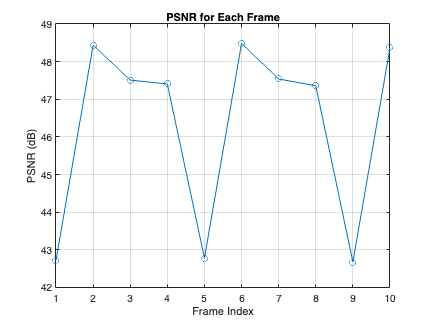


% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, psnrValuesPerFrame, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;

### 5. ﻿Exercise1-d. ﻿Note that you need to formulate a way to communicate the QP values...

% Start the timer
tic;

% decoding process
psnrValues_verify = A3_Decoding(filename_prefix, nframes, blockSize, paddedWidth, paddedHeight, ...
    height, width, QP_value, nRefFrame, ...
    FMEEnable, FastME, RCflag);

% Stop the timer and display the elapsed time
elapsedTime_de = toc;                      
fprintf('Total decoding time: %.2f seconds\n', elapsedTime_de);

Total decoding time: 1.86 seconds



% Compute and display average PSNR across all frames
averagePSNR_verify = mean(psnrValues_verify);
fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR_verify);

Average PSNR for the entire video: 11.25 dB



% Plot PSNR values over time (per frame)
figure;
plot(1:nframes, averagePSNR_verify, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title('PSNR for Each Frame');
grid on;dTime = toc;                     
fprintf('Total encoding time: %.2f seconds\n', elapsedTime);

Total encoding time: 3.43 seconds


### 6. Delieverable_Exercise1...

####     6.1 CIF video operations

% reading the file
cif_video = "CIF.yuv";

cif_width = 352;
cif_height = 288;
cif_nframes = 21;
cif_blocked_frame_cell_array = cell(1,300);

A1_Q3_extract_YOnly(cif_video, cif_height, cif_width, cif_nframes);

Y-only files Y!


% generating the Average Bit Counts VS QP values table
cif_filename_prefix = "A3_Exercise1_CIF_";

cif_blockSize = 16;
[cif_paddedWidth, cif_paddedHeight] = A1_Q3_paddingAndBlocking(cif_width, cif_height, ...
    cif_blockSize, cif_blocked_frame_cell_array, cif_nframes);

Y frame is split to blocks and padded as needed!



cif_n = 1;
cif_nRefFrame = 1

cif_nRefFrame = 1

cif_VBSEnable = true;
cif_MRFoverlay = 0;
cif_FMEEnable = true;
cif_FastME = true;
cif_searchRange = 16;

cif_I_Periods = [1, 21];

cif_QPValueCollections = 0:11;
cif_RCflag = false;
cif_targetBR = inf;

CIF_IAverageBitCounts = zeros(1, length(cif_QPValueCollections));
CIF_PAverageBitCounts = zeros(1, length(cif_QPValueCollections));


for I_period_idx = 1:length(cif_I_Periods)
    cif_I_period = cif_I_Periods(I_period_idx);

    for QP_idx = 1:length(cif_QPValueCollections)
        cif_QP_value = cif_QPValueCollections(QP_idx);
    
        fprintf('Processing QPs: %d.\n', cif_QP_value);

        [~, bitConsumptionPerFrame, rowBlockCountPerFrame] = A3_Encoding( ...
            cif_filename_prefix, cif_nframes, cif_paddedWidth, cif_paddedHeight, ...
            cif_blockSize, cif_height, cif_width, cif_searchRange, cif_n, cif_I_period, ...
            cif_QP_value, cif_nRefFrame, cif_VBSEnable, cif_MRFoverlay, cif_FMEEnable, cif_FastME, ...
            cif_RCflag, cif_targetBR, [], [], [], []);

        if I_period_idx == 1
            iTotalBitCounts = sum(bitConsumptionPerFrame);
            iTotalRowCounts = sum(rowBlockCountPerFrame);
            CIF_IAverageBitCounts(1, QP_idx) = round(iTotalBitCounts / iTotalRowCounts, 0);
            disp(CIF_IAverageBitCounts(1, QP_idx));
        else
            isPFrame = @(x) mod(x - 1, cif_I_period) ~= 0;
            pFrameIdx = arrayfun(isPFrame, 1:cif_nframes);

            bitConsumptionsInPFrame = bitConsumptionPerFrame(pFrameIdx);
            rowBlockCountInPFrame = rowBlockCountPerFrame(pFrameIdx);
            pTotalBitCounts = sum(bitConsumptionsInPFrame);
            pTotalRowCounts = sum(rowBlockCountInPFrame);
            CIF_PAverageBitCounts(1, QP_idx) = round(pTotalBitCounts / pTotalRowCounts, 0);
            disp(CIF_PAverageBitCounts(1, QP_idx));
        end     
    end
end

Processing QPs: 0.



disp(CIF_IAverageBitCounts);
disp(CIF_PAverageBitCounts);

save(strcat(cif_filename_prefix, 'CIF_IAverageBitCounts.mat'), 'CIF_IAverageBitCounts'); 
save(strcat(cif_filename_prefix, 'CIF_PAverageBitCounts.mat'), 'CIF_PAverageBitCounts');

% Print out the tables
load(strcat(cif_filename_prefix, 'CIF_IAverageBitCounts.mat'));
load(strcat(cif_filename_prefix, 'CIF_PAverageBitCounts.mat'));

CIF_IAverageBitCountsTable = array2table(CIF_IAverageBitCounts, ...
    'VariableNames', strcat("CIF_I_QP_", string(cif_QPValueCollections)));
rowNames = strcat("Average_BitCount_", string(cif_blockSize), ...
    "x", string(cif_blockSize));
CIF_IAverageBitCountsTable.Properties.RowNames = rowNames;
disp(CIF_IAverageBitCountsTable);

                              CIF_I_QP_0    CIF_I_QP_1    CIF_I_QP_2    CIF_I_QP_3    CIF_I_QP_4    CIF_I_QP_5    CIF_I_QP_6    CIF_I_QP_7    CIF_I_QP_8    CIF_I_QP_9    CIF_I_QP_10    CIF_I_QP_11
                              __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________

    Average_BitCount_16x16      24585         18669         13313          9039          5793          3568          2265          1483          1065          928            830   


CIF_PAverageBitCountsTable = array2table(CIF_PAverageBitCounts, ...
    'VariableNames', strcat("CIF_P_QP_", string(cif_QPValueCollections)));
rowNames = strcat("Average_BitCount_", string(cif_blockSize), ...
    "x", string(cif_blockSize));
CIF_PAverageBitCountsTable.Properties.RowNames = rowNames;
disp(CIF_PAverageBitCountsTable);

                              CIF_P_QP_0    CIF_P_QP_1    CIF_P_QP_2    CIF_P_QP_3    CIF_P_QP_4    CIF_P_QP_5    CIF_P_QP_6    CIF_P_QP_7    CIF_P_QP_8    CIF_P_QP_9    CIF_P_QP_10    CIF_P_QP_11
                              __________    __________    __________    __________    __________    __________    __________    __________    __________    __________    ___________    ___________

    Average_BitCount_16x16      25479         18595         12943          8624          5043          2851          1911          1529          1453          1404          1342   

Total encoding time: 1657.91 seconds


Average PSNR for the CIF video: 52.96 dB, I_Period = 1.


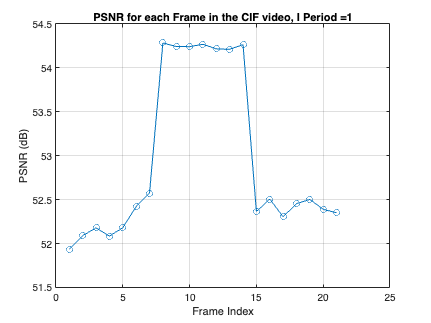

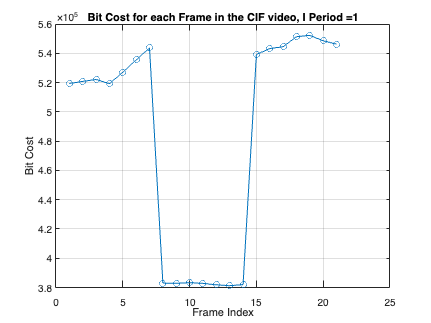

Total encoding time: 1671.79 seconds


Average PSNR for the CIF video: 50.63 dB, I_Period = 4.


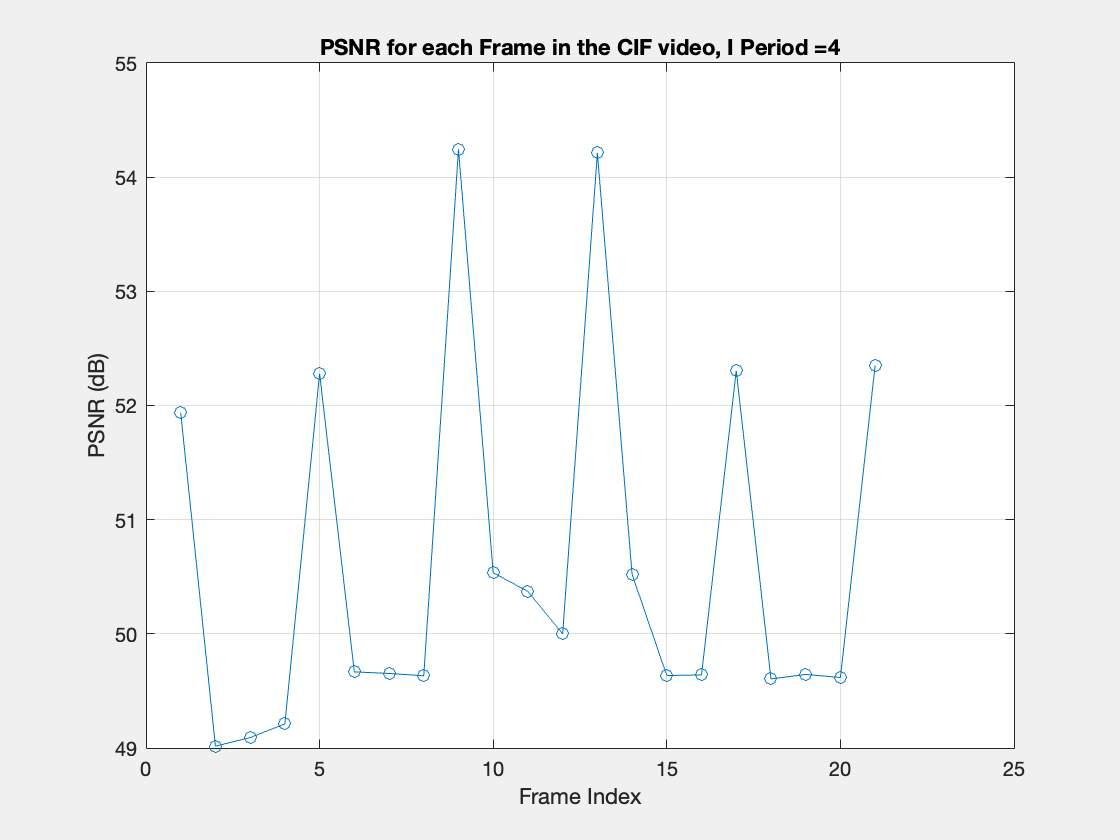

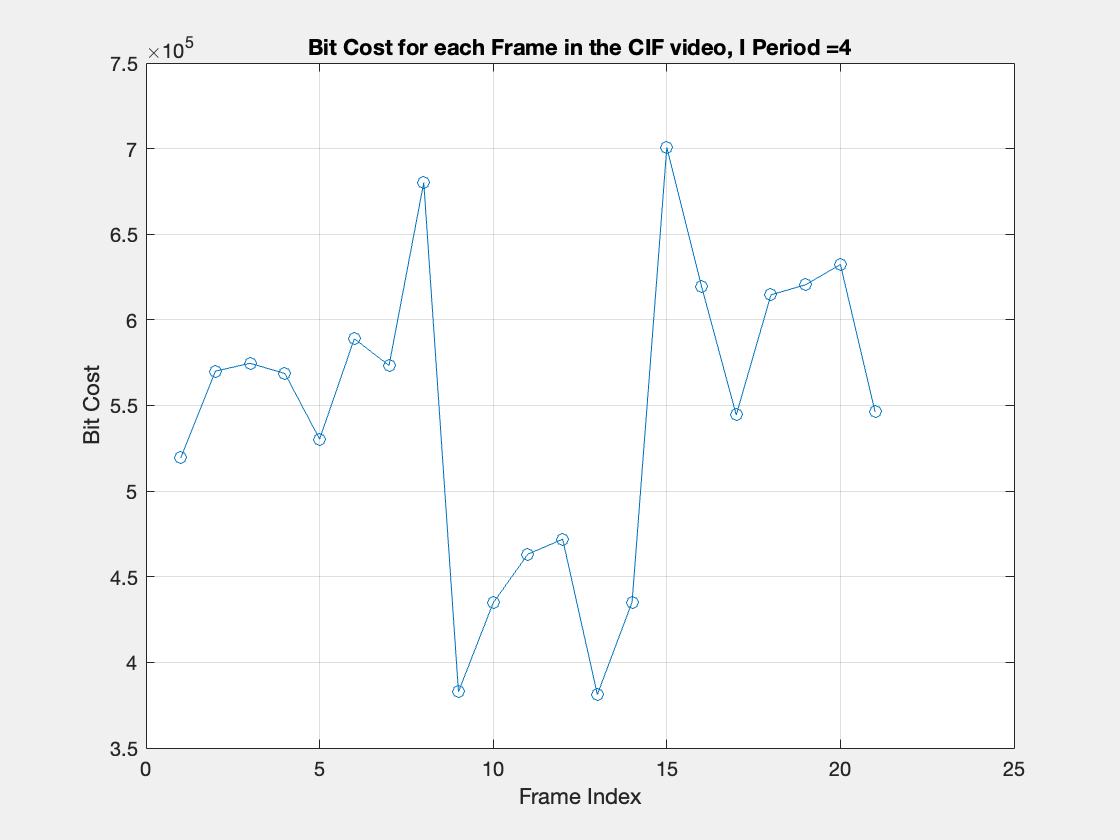

Total encoding time: 1684.78 seconds


Average PSNR for the CIF video: 49.66 dB, I_Period = 21.


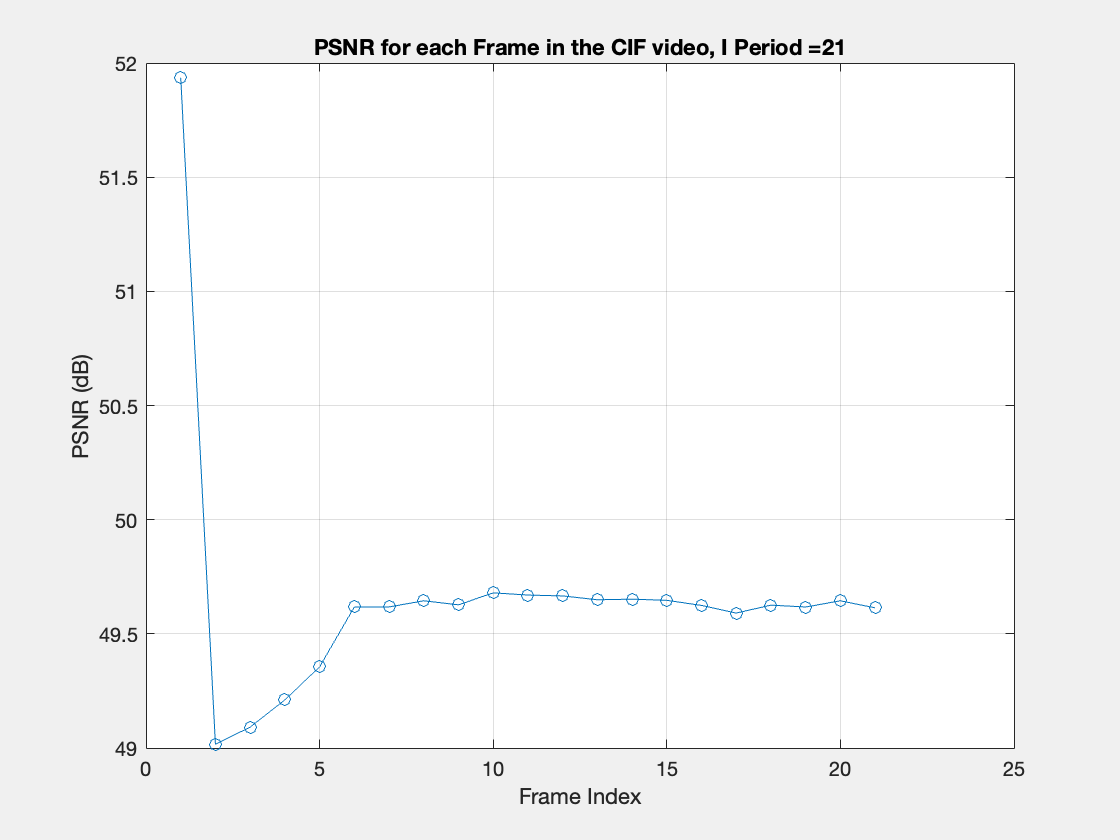

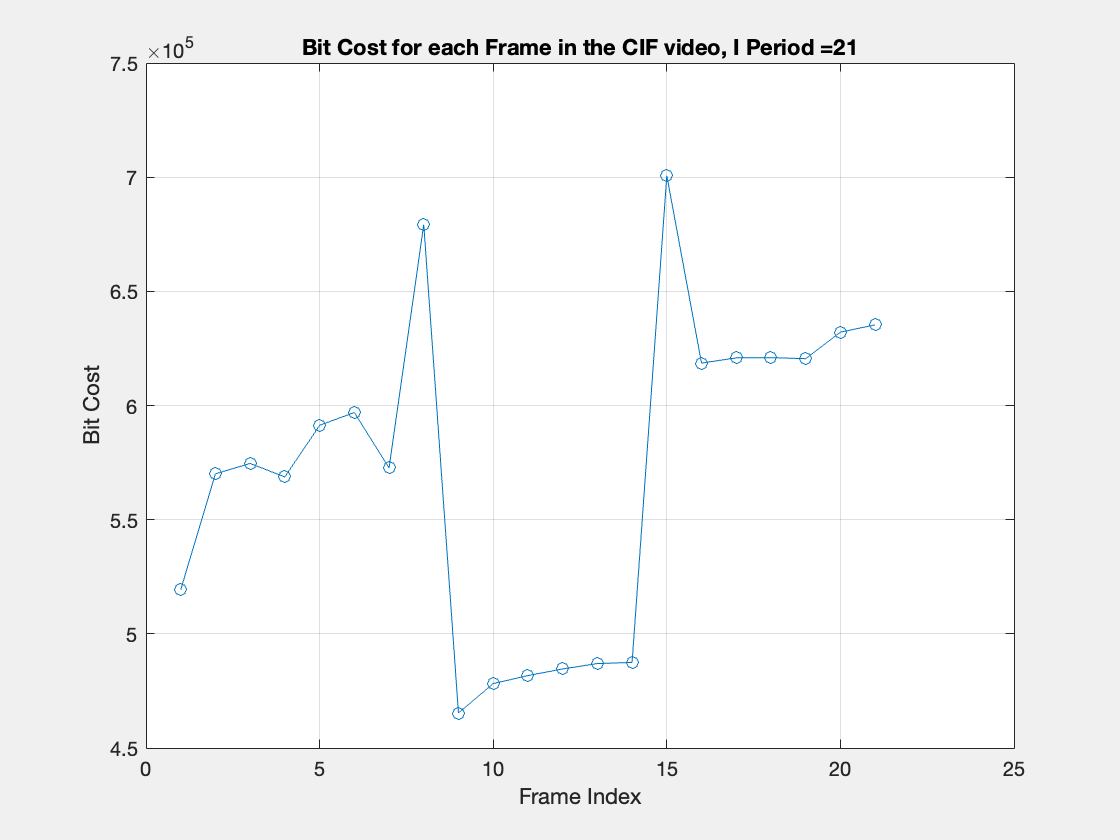

% encode with RCflag = true;
cif_RCflag = true;
cif_targetBR = 2.4 * 1140480;
cif_blockSizeCollections = [16];
cif_QPValueCollections = 0:11;
cif_I_Periods = [1, 4, 21];
cif_QP_value = 0; % just a placeholder
cif_totalBitCount21 = 0;
% Start the time

for cif_I_period_idx = 1:length(cif_I_Periods)
    cif_I_period = cif_I_Periods(cif_I_period_idx);
    cif_filename_prefix_2 = strcat("A3_Exercise1_CIF_Zout_", string(cif_I_period), "_");
    [psnrValuesPerFrame, bitConsumptionPerFrame, rowBlockCountPerFrame] = A3_Encoding( ...
        cif_filename_prefix_2, cif_nframes, cif_paddedWidth, cif_paddedHeight, ...
        cif_blockSize, cif_height, cif_width, cif_searchRange, cif_n, cif_I_period, cif_QP_value, ...
        cif_nRefFrame, cif_VBSEnable, cif_MRFoverlay, cif_FMEEnable, cif_FastME, ...
        cif_RCflag, cif_targetBR, CIF_IAverageBitCounts, CIF_PAverageBitCounts, ...
        cif_blockSizeCollections, cif_QPValueCollections);
    
    if cif_I_period == 21
        cif_totalBitCount21 = sum(bitConsumptionPerFrame);
    end
    % Stop the t ammer and display the elapsed time
    elapsedTime = toc;                     
    fprintf('Total encoding time: %.2f seconds\n', elapsedTime);
    
    % Compute and display average PSNR across all frames
    averagePSNR = mean(psnrValuesPerFrame);
    fprintf('Average PSNR for the CIF video: %.2f dB, I_Period = %d.\n', averagePSNR, cif_I_period);
    
    % Plot PSNR values over time (per frame)
    figure;
    plot(1:cif_nframes, psnrValuesPerFrame, '-o');
    xlabel('Frame Index');
    ylabel('PSNR (dB)');
    title(strcat('PSNR for each Frame in the CIF video, I Period = ', string(cif_I_period)));
    grid on;

    figure;
    plot(1:cif_nframes, bitConsumptionPerFrame, '-o');
    xlabel('Frame Index');
    ylabel('Bit Cost');
    title(strcat('Bit Cost for each Frame in the CIF video, I Period = ', string(cif_I_period)));
    grid on;

    set(0, 'DefaultFigureVisible', 'on');
end

Total decoding time: 3.72 seconds


Average PSNR for the entire video: 10.28 dB


Total decoding time: 6.45 seconds


Average PSNR for the entire video: 9.62 dB


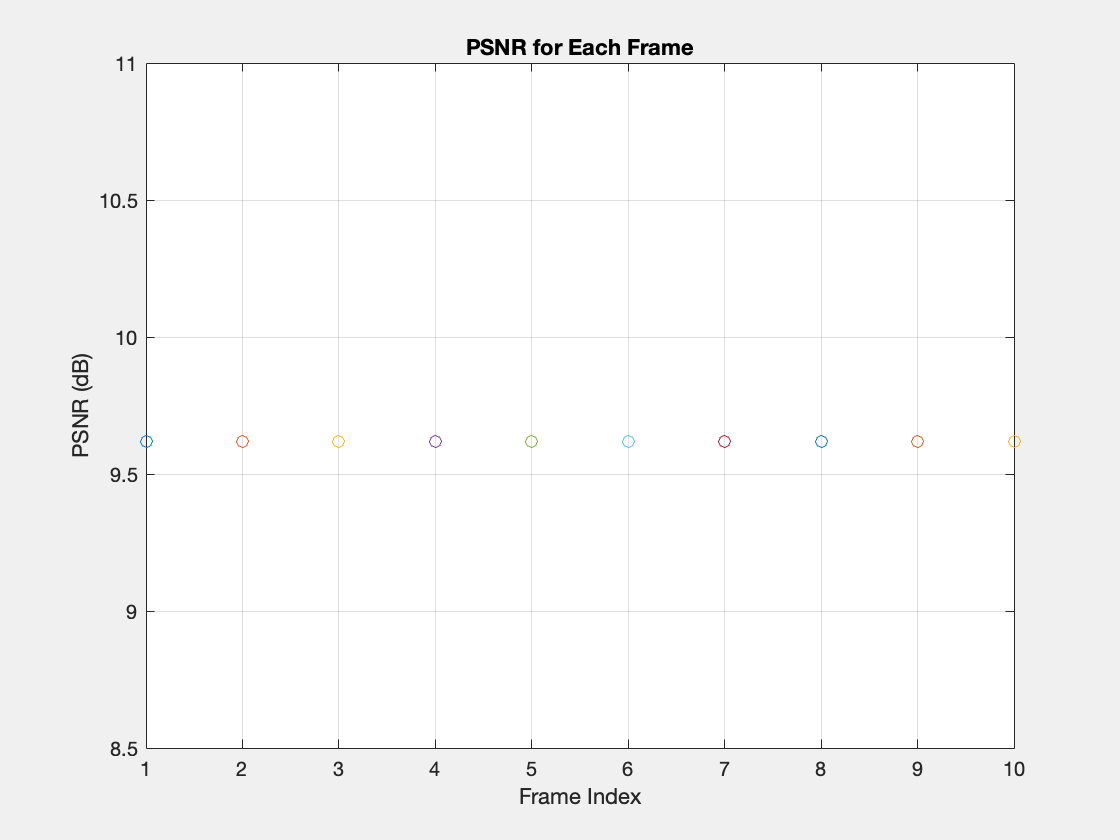

Total decoding time: 8.46 seconds


Average PSNR for the entire video: 11.75 dB


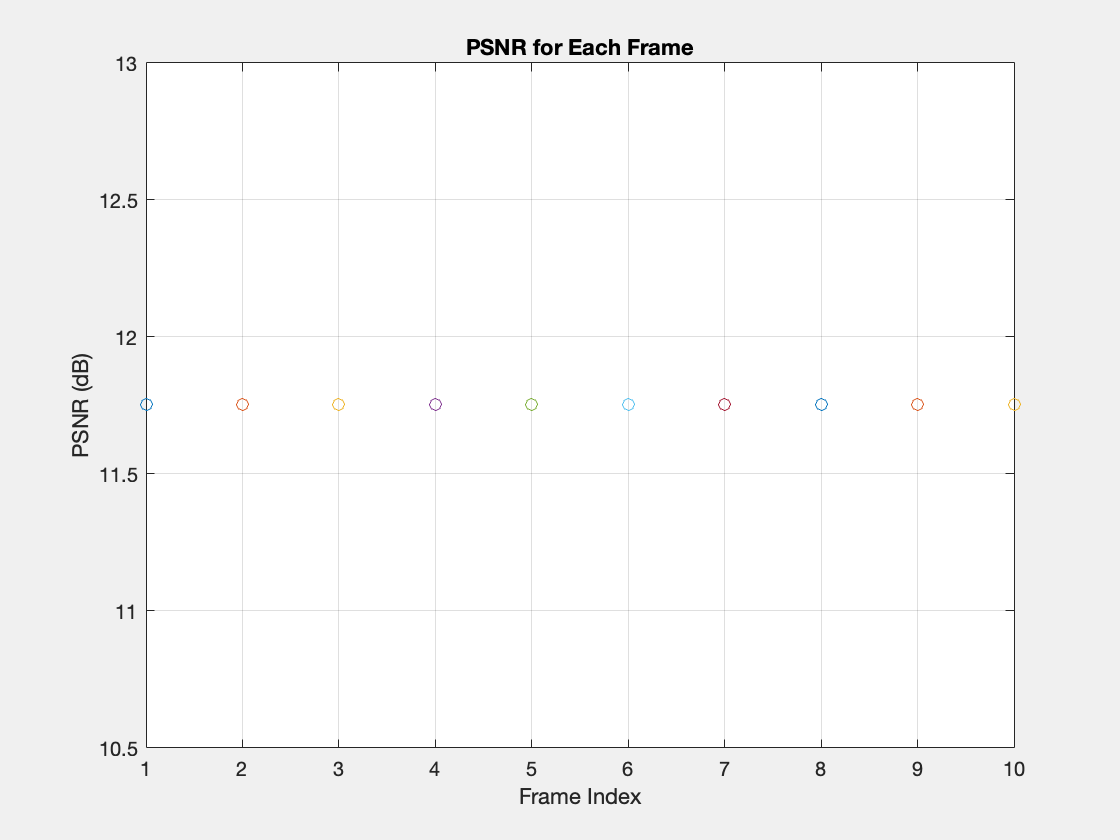

% decode with RCflag = true;
% Start the timer
tic;

for cif_I_period_idx = 1:length(cif_I_Periods)
    cif_I_period = cif_I_Periods(cif_I_period_idx);
    cif_filename_prefix_2 = strcat("A3_Exercise1_CIF_Zout_", string(cif_I_period), "_");
    psnrValues_verify = A3_Decoding(cif_filename_prefix_2, cif_nframes, cif_blockSize, ...
        cif_paddedWidth, cif_paddedHeight, cif_height, cif_width, cif_QP_value, cif_nRefFrame, ...
        cif_FMEEnable, cif_FastME, cif_RCflag);
    
    % Stop the timer and display the elapsed time
    elapsedTime_de = toc;                      
    fprintf('Total decoding time: %.2f seconds\n', elapsedTime_de);
    
    % Compute and display average PSNR across all frames
    averagePSNR_verify = mean(psnrValues_verify);
    fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR_verify);
    
    % Plot PSNR values over time (per frame)
    figure;
    plot(1:cif_nframes, averagePSNR_verify, '-o');
    xlabel('Frame Index');
    ylabel('PSNR (dB)');
    title('PSNR for Each Frame');
    grid on;

    set(0, 'DefaultFigureVisible', 'on');
end

% For I_period = 21 senario
disp(cif_totalBitCount21);

    12006184




cif_prevAbsBitCountDiff = inf;
cif_absBitCountDiff = zeros(1, 12);

cif_RCflag = false;
cif_targetBR = inf;

for fixedQP = 0:11

    [~, currBitConsumptionPerFrame, ~] = A3_Encoding( ...
        cif_filename_prefix_2, cif_nframes, cif_paddedWidth, cif_paddedHeight, ...
        cif_blockSize, cif_height, cif_width, cif_searchRange, cif_n, 21, ...
        fixedQP, cif_nRefFrame, cif_VBSEnable, cif_MRFoverlay, cif_FMEEnable, cif_FastME, ...
        cif_RCflag, cif_targetBR, [], [], [], []);

    cif_currentAbsBitCountDiff = abs(sum(currBitConsumptionPerFrame) - cif_totalBitCount21);
    cif_absBitCountDiff(1, fixedQP + 1) = cif_currentAbsBitCountDiff;
end

[val, idx] = min(cif_absBitCountDiff);
disp(cif_absBitCountDiff);

     2347996     4942535     7079365     8713286    10071427    10908624    11274112    11427277    11463167    11483344    11506992    11547972




disp(strcat("Finding the optimal fixing QP is ",  string(idx - 1), "."));

Finding the optimal fixing QP is 0.



[psnrValuesForClosetQP, bitConsumptionPerFrameForCloseQP, ~] = A3_Encoding( ...
    cif_filename_prefix_2, cif_nframes, cif_paddedWidth, cif_paddedHeight, ...
    cif_blockSize, cif_height, cif_width, cif_searchRange, cif_n, 21, ...
    idx - 1, cif_nRefFrame, cif_VBSEnable, cif_MRFoverlay, cif_FMEEnable, cif_FastME, ...
    cif_RCflag, cif_targetBR, [], [], [], []);

averagePSNRForCloseQP = mean(psnrValuesForClosetQP);
fprintf('Average PSNR for the CIF video: %.2f dB, I_Period = %d.\n', averagePSNRForCloseQP, cif_I_period);

Average PSNR for the CIF video: 47.83 dB, I_Period = 21.


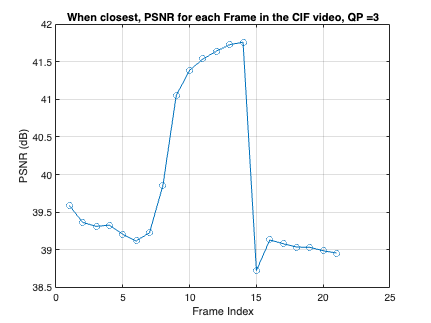


% Plot PSNR values over time (per frame)
figure;
plot(1:cif_nframes, psnrValuesForClosetQP, '-o');
xlabel('Frame Index');
ylabel('PSNR (dB)');
title(strcat('When closest, PSNR for each Frame in the CIF video, QP = ', string(idx - 1)));
grid on;

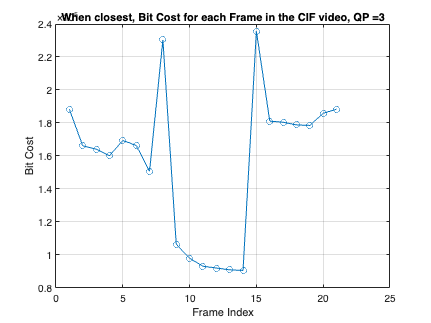


figure;
plot(1:cif_nframes, bitConsumptionPerFrameForCloseQP, '-o');
xlabel('Frame Index');
ylabel('Bit Cost');
title(strcat('When closest, Bit Cost for each Frame in the CIF video, QP = ', string(idx - 1)));
grid on;


set(0, 'DefaultFigureVisible', 'on');

#### 6.2 QCIF video operations

% reading the file
qcif_video = "QCIF.yuv";

qcif_width = 176;
qcif_height = 144;
qcif_nframes = 21;
qcif_blocked_frame_cell_array = cell(1,300);

A1_Q3_extract_YOnly(qcif_video, qcif_height, qcif_width, qcif_nframes);

Y-only files Y!


% generating the Average Bit Counts VS QP values table
qcif_filename_prefix = "A3_Exercise1_QCIF_";

qcif_blockSize = 16;
[qcif_paddedWidth, qcif_paddedHeight] = A1_Q3_paddingAndBlocking(qcif_width, qcif_height, ...
    qcif_blockSize, qcif_blocked_frame_cell_array, qcif_nframes);

Y frame is split to blocks and padded as needed!



qcif_n = 1;
qcif_nRefFrame = 1

qcif_nRefFrame = 1

qcif_VBSEnable = true;
qcif_MRFoverlay = 0;
qcif_FMEEnable = true;
qcif_FastME = true;
qcif_searchRange = 16;

qcif_I_Periods = [1, 21];

qcif_QPValueCollections = 0:11;
qcif_RCflag = false;
qcif_targetBR = inf;

QCIF_IAverageBitCounts = zeros(1, length(qcif_QPValueCollections));
QCIF_PAverageBitCounts = zeros(1, length(qcif_QPValueCollections));


for I_period_idx = 1:length(qcif_I_Periods)
    qcif_I_period = qcif_I_Periods(I_period_idx);

    for QP_idx = 1:length(qcif_QPValueCollections)
        qcif_QP_value = qcif_QPValueCollections(QP_idx);
    
        fprintf('Processing QPs: %d.\n', qcif_QP_value);

        [~, bitConsumptionPerFrame, rowBlockCountPerFrame] = A3_Encoding( ...
            qcif_filename_prefix, qcif_nframes, qcif_paddedWidth, qcif_paddedHeight, ...
            qcif_blockSize, qcif_height, qcif_width, qcif_searchRange, qcif_n, qcif_I_period, ...
            qcif_QP_value, qcif_nRefFrame, qcif_VBSEnable, qcif_MRFoverlay, qcif_FMEEnable, ...
            qcif_FastME, qcif_RCflag, qcif_targetBR, [], [], [], []);

        if I_period_idx == 1
            iTotalBitCounts = sum(bitConsumptionPerFrame);
            iTotalRowCounts = sum(rowBlockCountPerFrame);
            QCIF_IAverageBitCounts(1, QP_idx) = round(iTotalBitCounts / iTotalRowCounts, 0);
        else
            isPFrame = @(x) mod(x-1, qcif_I_period) ~= 0;
            pFrameIdx = arrayfun(isPFrame, 1:qcif_nframes);

            bitConsumptionsInPFrame = bitConsumptionPerFrame(pFrameIdx);
            rowBlockCountInPFrame = rowBlockCountPerFrame(pFrameIdx);
            pTotalBitCounts = sum(bitConsumptionsInPFrame);
            pTotalRowCounts = sum(rowBlockCountInPFrame);
            QCIF_PAverageBitCounts(1, QP_idx) = round(pTotalBitCounts / pTotalRowCounts, 0);
        end     
    end
end

Processing QPs: 0.
Processing QPs: 1.
Processing QPs: 2.
Processing QPs: 3.



disp(QCIF_IAverageBitCounts);
disp(QCIF_PAverageBitCounts);

save(strcat(qcif_filename_prefix, 'QCIF_IAverageBitCounts.mat'), 'QCIF_IAverageBitCounts'); 
save(strcat(qcif_filename_prefix, 'QCIF_PAverageBitCounts.mat'), 'QCIF_PAverageBitCounts');

% Print out the tables
load(strcat(qcif_filename_prefix, 'QCIF_IAverageBitCounts.mat'));
load(strcat(qcif_filename_prefix, 'QCIF_PAverageBitCounts.mat'));

QCIF_IAverageBitCountsTable = array2table(QCIF_IAverageBitCounts, ...
    'VariableNames', strcat("QCIF_I_QP_", string(qcif_QPValueCollections)));
rowNames = strcat("Average_BitCount_", string(qcif_blockSize), ...
    "x", string(qcif_blockSize));
QCIF_IAverageBitCountsTable.Properties.RowNames = rowNames;
disp(QCIF_IAverageBitCountsTable);

                              QCIF_I_QP_0    QCIF_I_QP_1    QCIF_I_QP_2    QCIF_I_QP_3    QCIF_I_QP_4    QCIF_I_QP_5    QCIF_I_QP_6    QCIF_I_QP_7    QCIF_I_QP_8    QCIF_I_QP_9    QCIF_I_QP_10    QCIF_I_QP_11
                              ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ____________    ____________

    Average_BitCount_16x16       13314          10259          7609           5557           3892           2559           1593            966            61


QCIF_PAverageBitCountsTable = array2table(QCIF_PAverageBitCounts, ...
    'VariableNames', strcat("QCIF_P_QP_", string(qcif_QPValueCollections)));
rowNames = strcat("Average_BitCount_", string(qcif_blockSize), ...
    "x", string(qcif_blockSize));
QCIF_PAverageBitCountsTable.Properties.RowNames = rowNames;
disp(QCIF_PAverageBitCountsTable);

                              QCIF_P_QP_0    QCIF_P_QP_1    QCIF_P_QP_2    QCIF_P_QP_3    QCIF_P_QP_4    QCIF_P_QP_5    QCIF_P_QP_6    QCIF_P_QP_7    QCIF_P_QP_8    QCIF_P_QP_9    QCIF_P_QP_10    QCIF_P_QP_11
                              ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ____________    ____________

    Average_BitCount_16x16       12555          9229           6470           4380           2810           1755           1135            832            77

Total encoding time: 3.78 seconds


Average PSNR for the QCIF video: 43.25 dB, I_Period = 1.


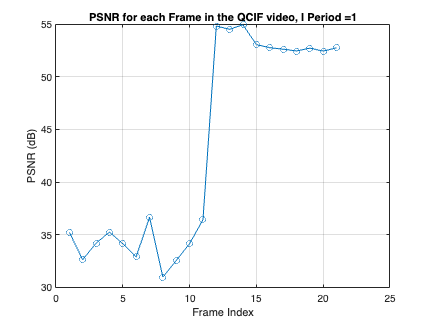

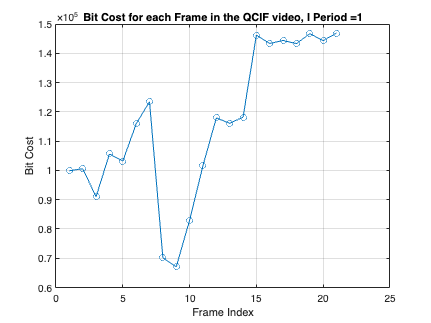

Total encoding time: 6.08 seconds


Average PSNR for the QCIF video: 38.30 dB, I_Period = 4.


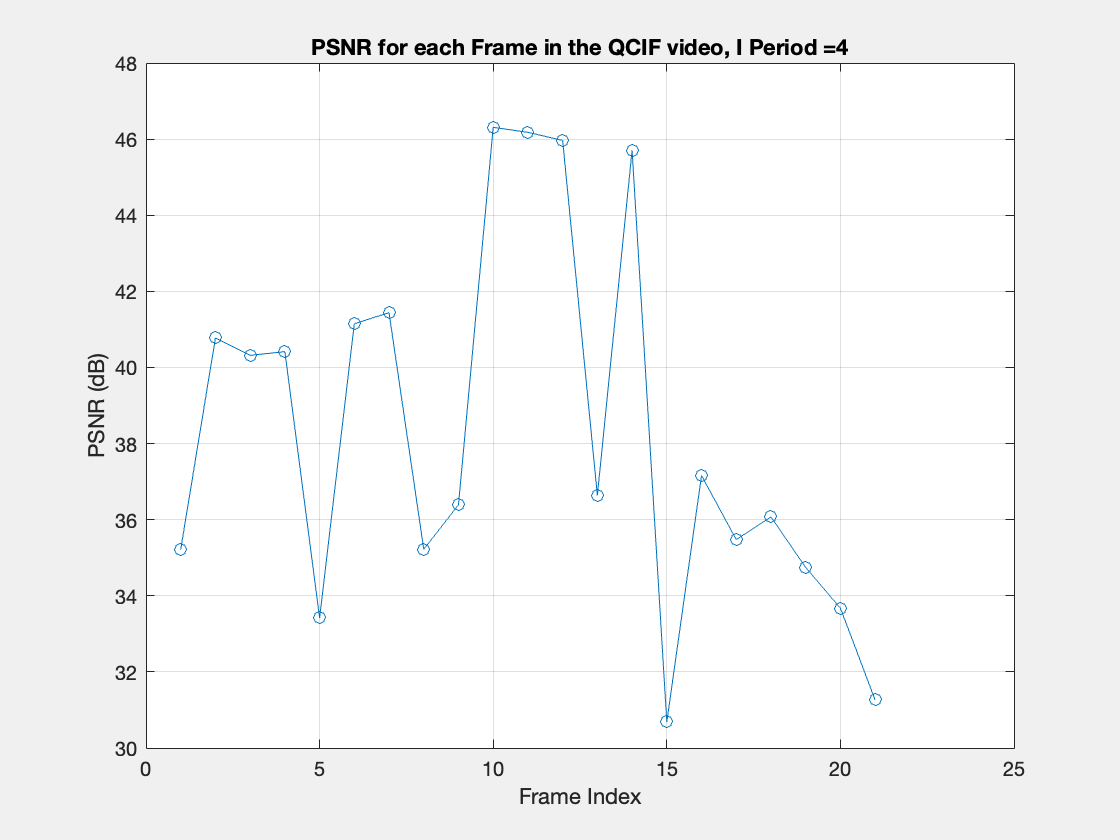

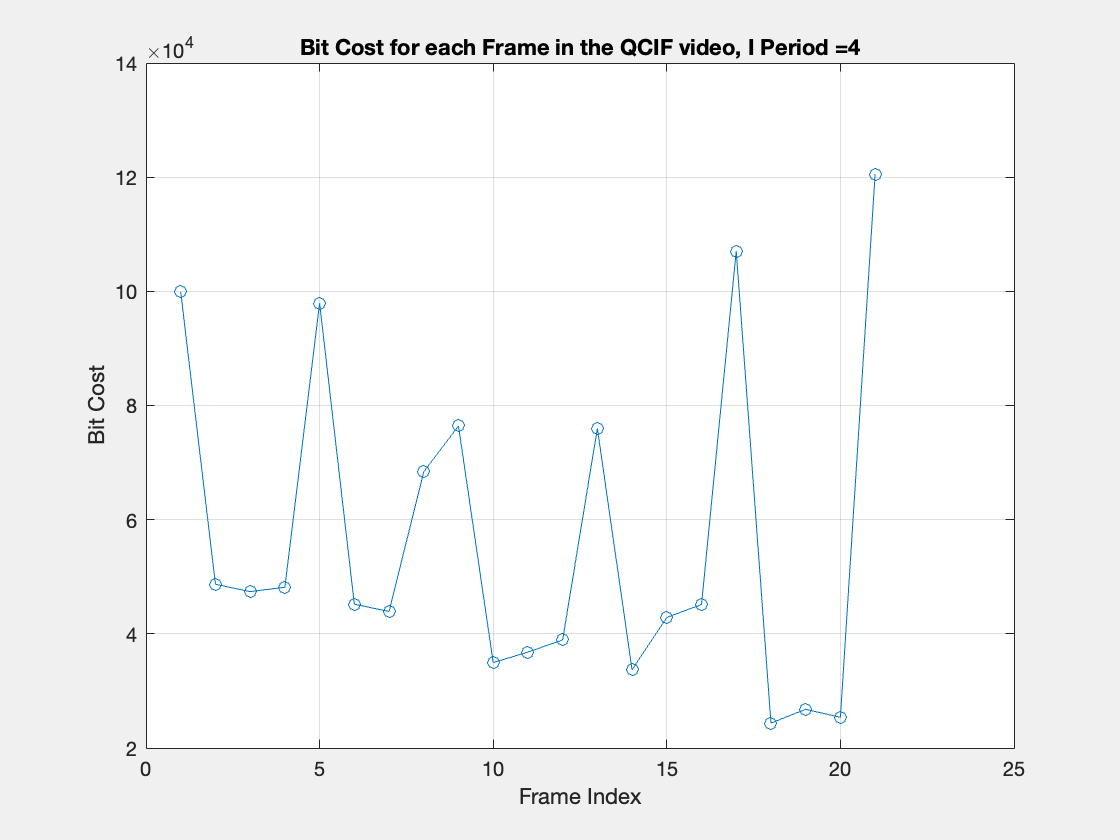

Total encoding time: 8.11 seconds


Average PSNR for the QCIF video: 39.79 dB, I_Period = 21.


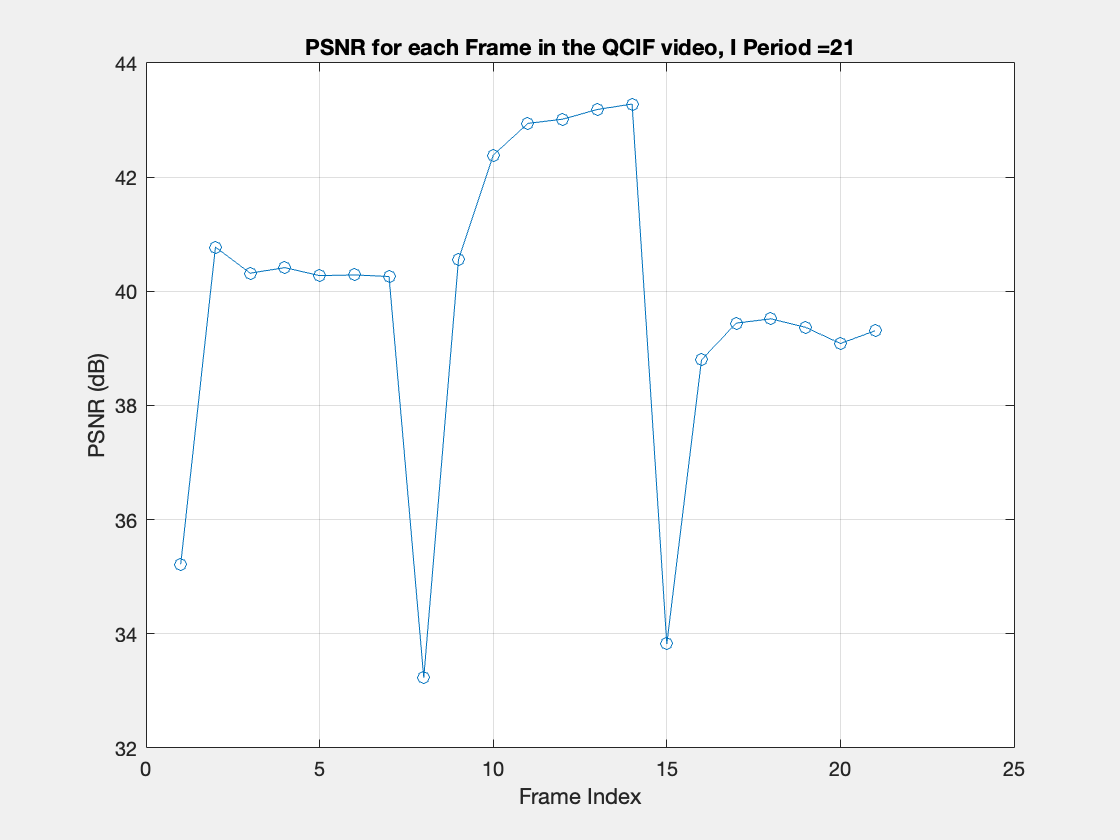

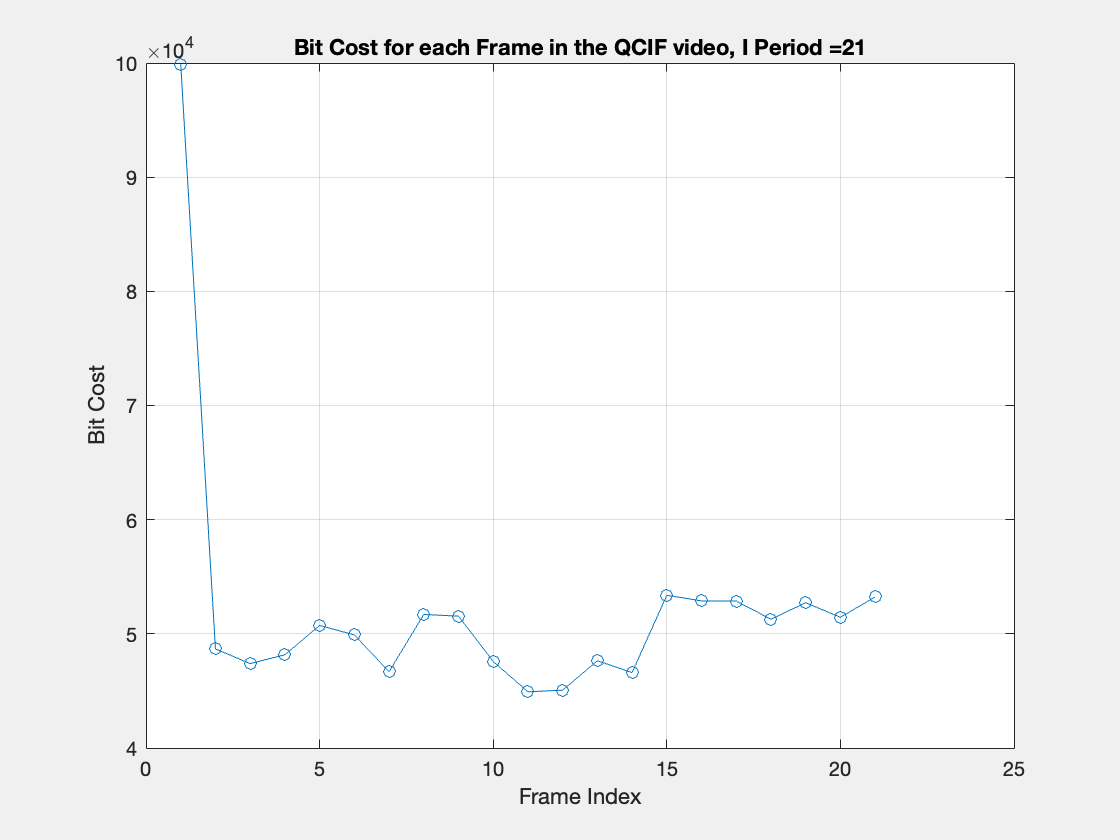

% encode with RCflag = true;
qcif_filename_prefix_2 = "A3_Exercise1_QCIF_Zout_";

qcif_RCflag = true;
qcif_targetBR = 0.96 * 1140480;
qcif_blockSizeCollections = [16];
qcif_QPValueCollections = 0:11;
qcif_I_Periods = [1, 4, 21];
qcif_QP_value = 0; % just a placeholder

% Start the timer
tic;

for qcif_I_period_idx = 1:length(qcif_I_Periods)
    qcif_I_period = qcif_I_Periods(qcif_I_period_idx);
    qcif_filename_prefix_2 = strcat("A3_Exercise1_QCIF_Zout_", string(qcif_I_period), "_");
    [psnrValuesPerFrame, bitConsumptionPerFrame, rowBlockCountPerFrame] = A3_Encoding( ...
        qcif_filename_prefix_2, qcif_nframes, qcif_paddedWidth, qcif_paddedHeight, ...
        qcif_blockSize, qcif_height, qcif_width, qcif_searchRange, qcif_n, qcif_I_period, ...
        qcif_QP_value, qcif_nRefFrame, qcif_VBSEnable, cif_MRFoverlay, ...
        qcif_FMEEnable, qcif_FastME, qcif_RCflag, qcif_targetBR, ...
        QCIF_IAverageBitCounts, QCIF_PAverageBitCounts, ...
        qcif_blockSizeCollections, qcif_QPValueCollections);
    
    % Stop the t ammer and display the elapsed time
    elapsedTime = toc;                     
    fprintf('Total encoding time: %.2f seconds\n', elapsedTime);
    
    % Compute and display average PSNR across all frames
    averagePSNR = mean(psnrValuesPerFrame);
    fprintf('Average PSNR for the QCIF video: %.2f dB, I_Period = %d.\n', averagePSNR, qcif_I_period);
    
    % Plot PSNR values over time (per frame)
    figure;
    plot(1:cif_nframes, psnrValuesPerFrame, '-o');
    xlabel('Frame Index');
    ylabel('PSNR (dB)');
    title(strcat('PSNR for each Frame in the QCIF video, I Period = ', string(qcif_I_period)));
    grid on;

    figure;
    plot(1:cif_nframes, bitConsumptionPerFrame, '-o');
    xlabel('Frame Index');
    ylabel('Bit Cost');
    title(strcat('Bit Cost for each Frame in the QCIF video, I Period = ', string(qcif_I_period)));
    grid on;

    set(0, 'DefaultFigureVisible', 'on');
end

Total decoding time: 0.93 seconds


Average PSNR for the entire video: 9.95 dB


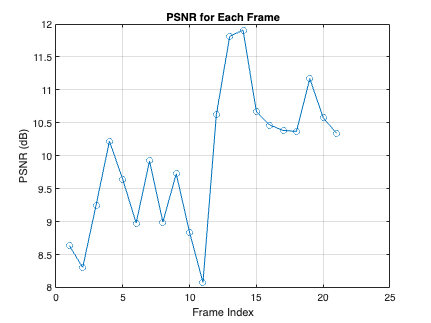

Total decoding time: 1.69 seconds


Average PSNR for the entire video: 9.44 dB


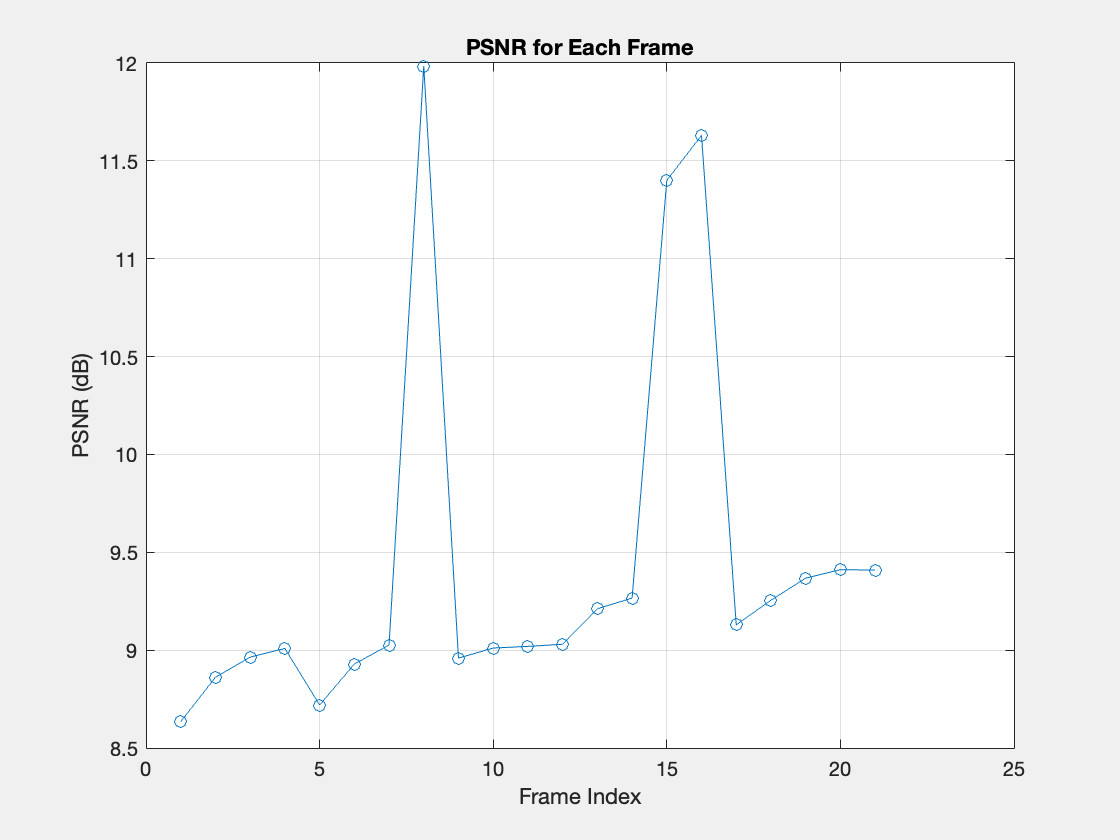

Total decoding time: 2.34 seconds


Average PSNR for the entire video: 11.22 dB


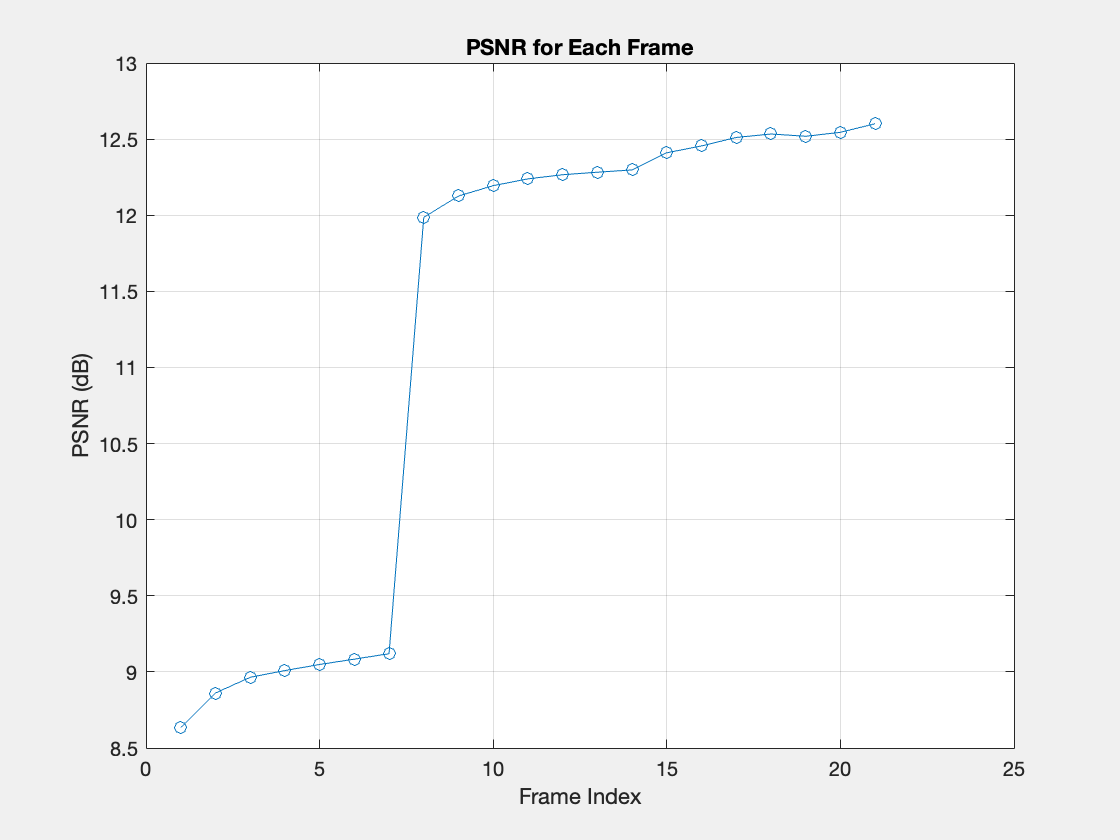

% decode with RCflag = true;
% Start the timer
tic;

for qcif_I_period_idx = 1:length(qcif_I_Periods)
    qcif_I_period = qcif_I_Periods(qcif_I_period_idx);
    qcif_filename_prefix_2 = strcat("A3_Exercise1_QCIF_Zout_", string(qcif_I_period), "_");
    psnrValues_verify = A3_Decoding(qcif_filename_prefix_2, qcif_nframes, qcif_blockSize, ...
        qcif_paddedWidth, qcif_paddedHeight, qcif_height, qcif_width, qcif_QP_value, qcif_nRefFrame, ...
        qcif_FMEEnable, qcif_FastME, qcif_RCflag);
    
    % Stop the timer and display the elapsed time
    elapsedTime_de = toc;                      
    fprintf('Total decoding time: %.2f seconds\n', elapsedTime_de);
    
    % Compute and display average PSNR across all frames
    averagePSNR_verify = mean(psnrValues_verify);
    fprintf('Average PSNR for the entire video: %.2f dB\n', averagePSNR_verify);
    
    % Plot PSNR values over time (per frame)
    figure;
    plot(1:qcif_nframes, psnrValues_verify, '-o');
    xlabel('Frame Index');
    ylabel('PSNR (dB)');
    title('PSNR for Each Frame');
    grid on;

    set(0, 'DefaultFigureVisible', 'on');
end